2.1有理函数z变换的部分分式展开

B = [18];
A = [18,3,-4,-1];
[R,P,K] = residuez(B,A)

R =     0.3600
    0.2400
    0.4000


P =     0.5000
   -0.3333
   -0.3333



K =

     []



2.2系统函数的零极点分析

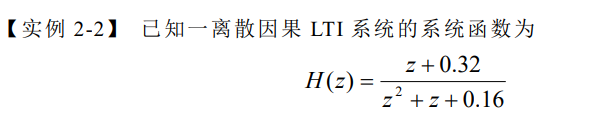

求该系统的零极点

B = [1,0.32];
A = [1,1,0.16];
[R,P,K] = tf2zp(B,A)

R = -0.3200

P =    -0.8000
   -0.2000


K = 1

零极点分布图

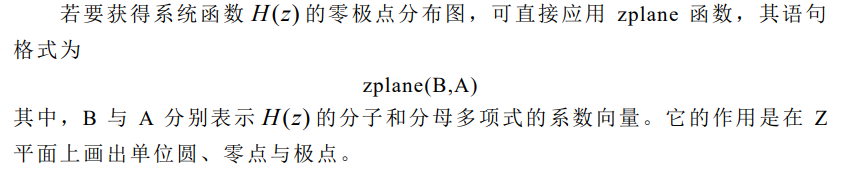

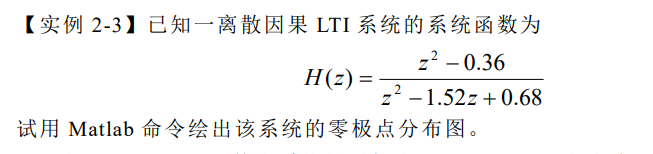

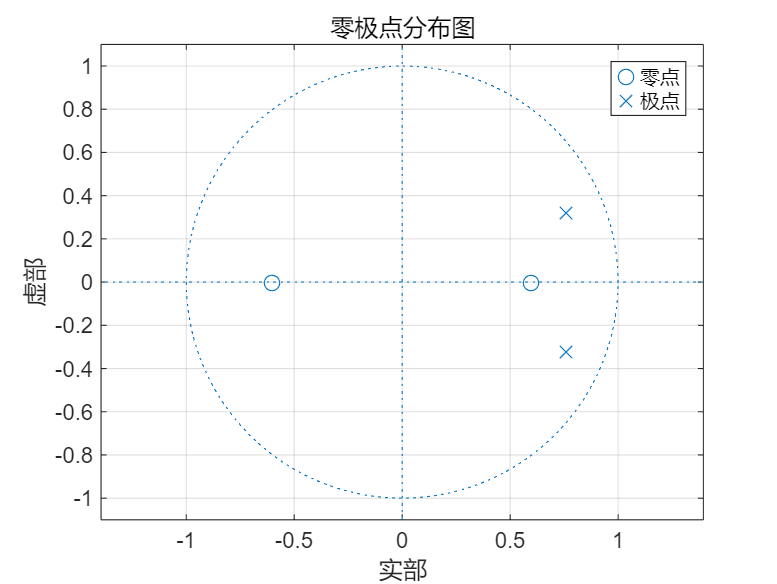

B = [1,0,-0.36];
A = [1,-1.52,0.68];
zplane(B,A),grid on
legend("零点","极点");
title('零极点分布图');

2.3系统函数的零极点分布与其时域特性的关系

1.

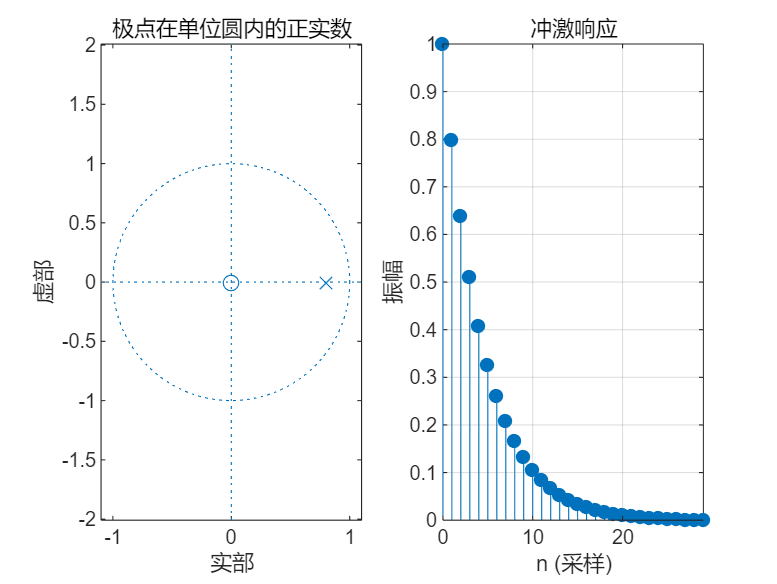

b1 = [1,0];
a1 = [1,-0.8];
subplot(121)
zplane(b1,a1)
title('极点在单位圆内的正实数')
subplot(122)
impz(b1,a1,30);grid on;

figure

2.

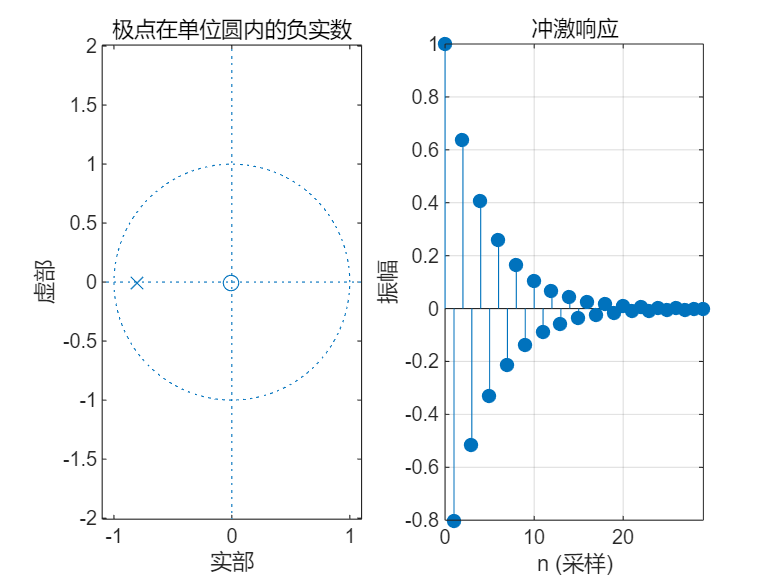

b2 = [1,0];
a2 = [1,0.8];
subplot(121)
zplane(b2,a2)
title('极点在单位圆内的负实数')
subplot(122)
impz(b2,a2,30);grid on;

figure

3.

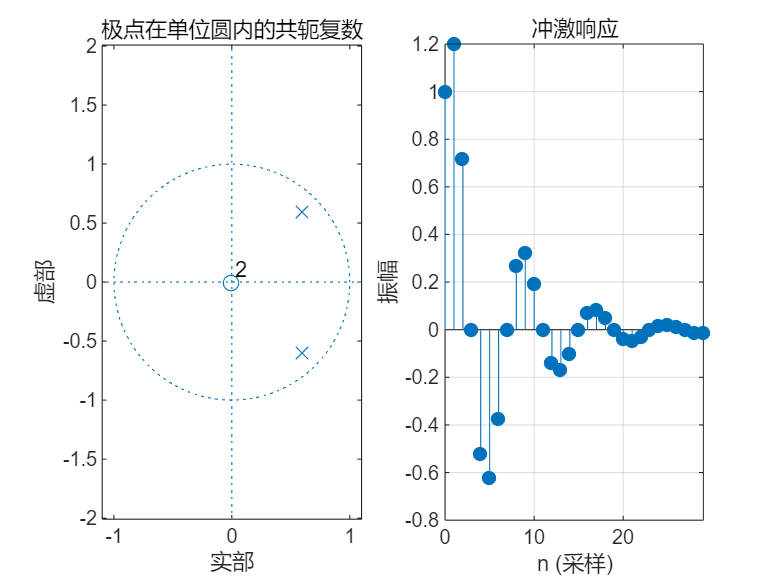

b3 = [1,0];
a3 = [1,-1.2,0.72];
subplot(121)
zplane(b3,a3)
title('极点在单位圆内的共轭复数')
subplot(122)
impz(b3,a3,30);grid on;

figure

4.

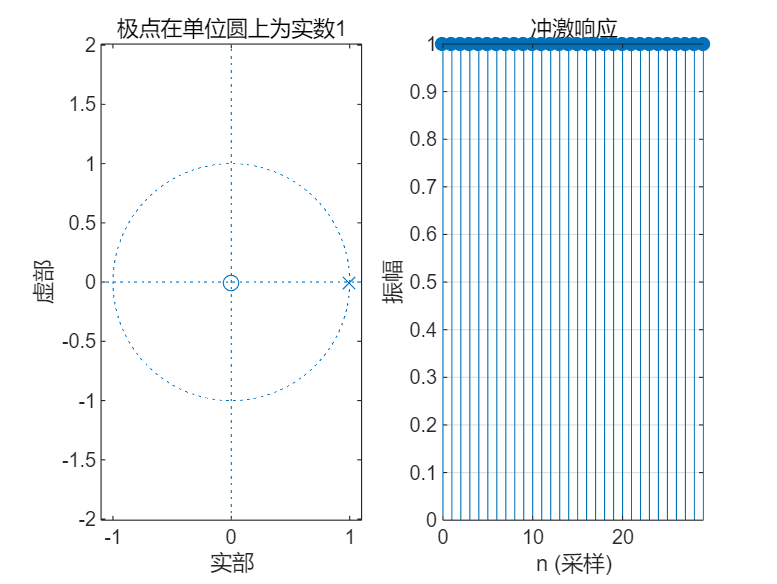

b4 = [1,0];
a4 = [1,-1];
subplot(121)
zplane(b4,a4)
title('极点在单位圆上为实数1')
subplot(122)
impz(b4,a4,30);grid on;

figure

5.

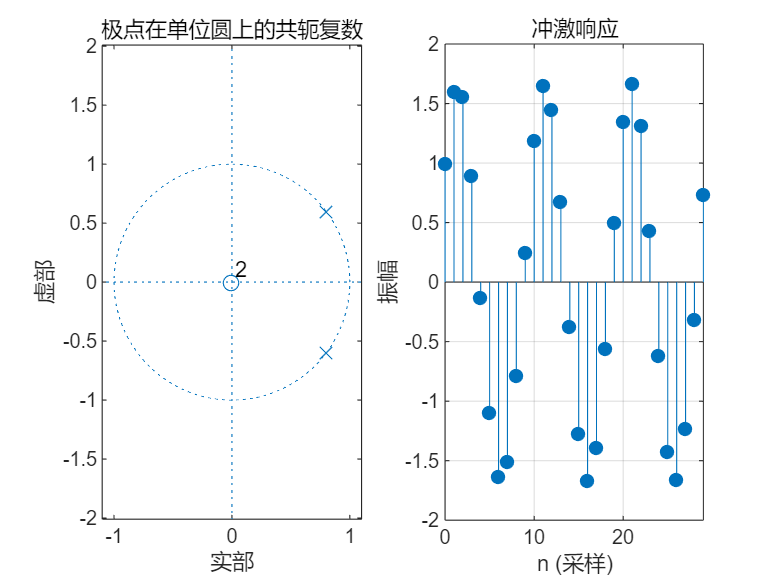

b5 = [1,0];
a5 = [1,-1.6,1];
subplot(121)
zplane(b5,a5)
title('极点在单位圆上的共轭复数')
subplot(122)
impz(b5,a5,30);grid on;

figure

6.

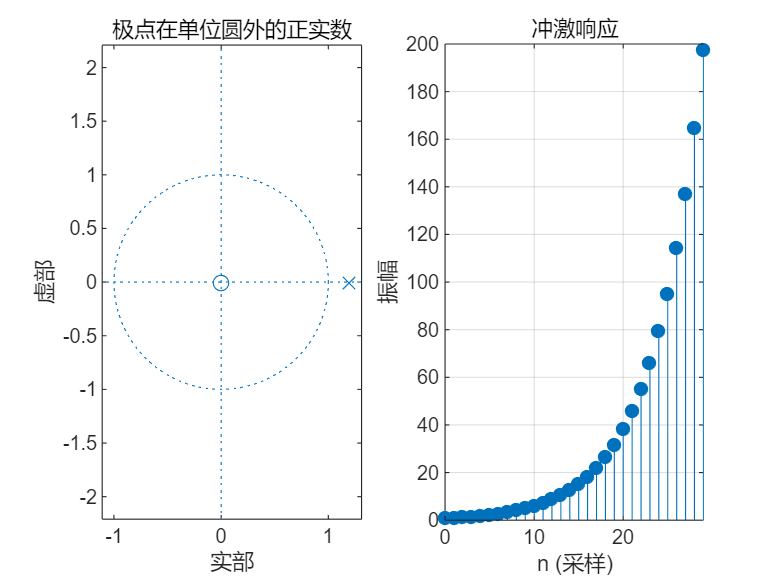

b6 = [1,0];
a6 = [1,-1.2];
subplot(121)
zplane(b6,a6)
title('极点在单位圆外的正实数')
subplot(122)
impz(b6,a6,30);grid on;

figure

7.

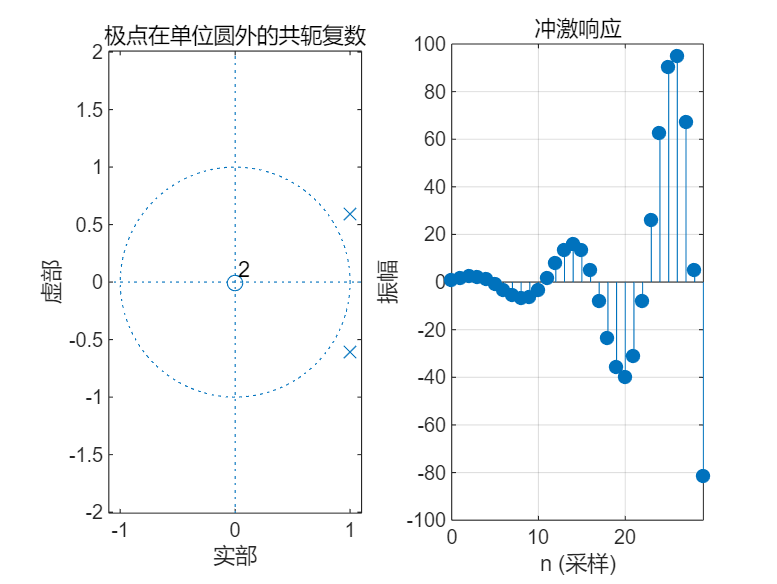

b7 = [1,0];
a7 = [1,-2,1.36];
subplot(121)
zplane(b7,a7)
title('极点在单位圆外的共轭复数')
subplot(122)
impz(b7,a7,30);grid on;

figure

2.4离散时间LTI系统的频率特性分析

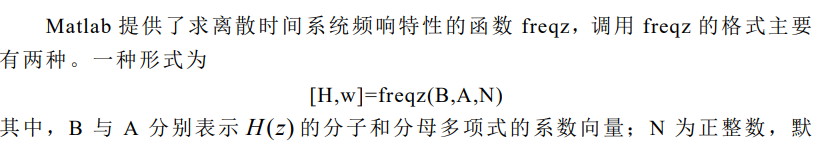

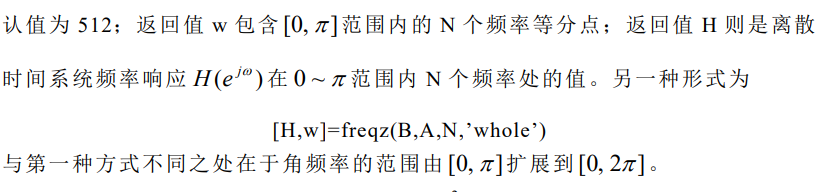

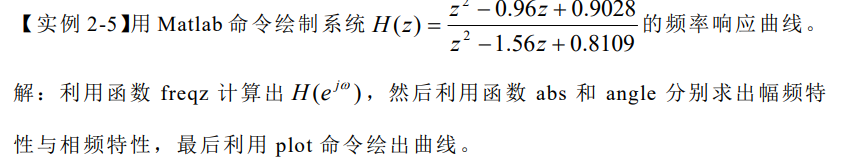

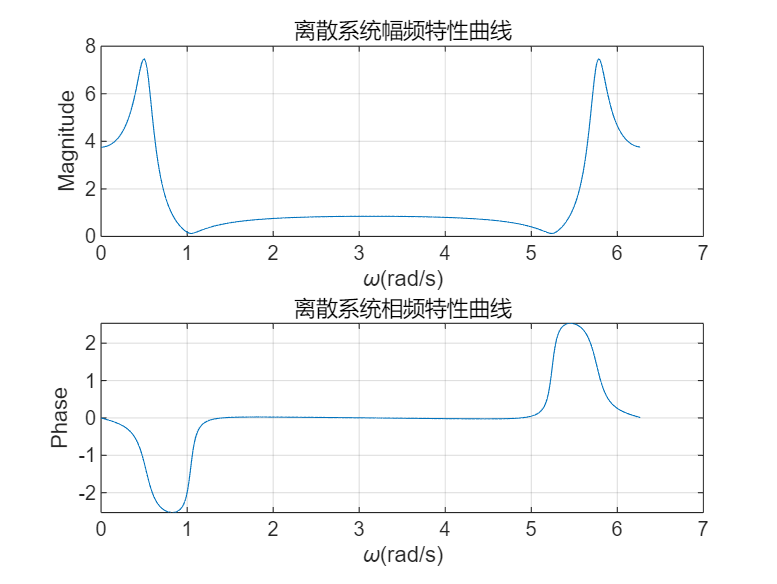

b = [1 -0.96 0.9028];
a = [1 -1.56 0.8109];
[H,w] = freqz(b,a,400,'whole');
Hm = abs(H);
Hp = angle(H);
subplot(211)
plot(w,Hm),grid on
xlabel('\omega(rad/s)'),ylabel('Magnitude')
title('离散系统幅频特性曲线')
subplot(212)
plot(w,Hp),grid on
xlabel('\omega(rad/s)'),ylabel('Phase')
title('离散系统相频特性曲线')

实验内容

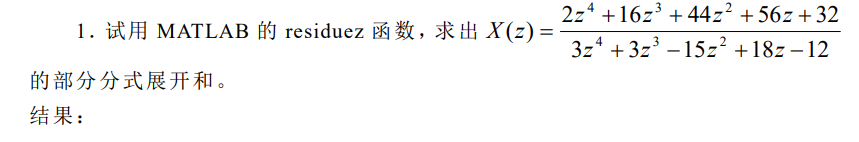

B = [2, 16, 44, 56, 32];

A = [3, 3, -15, 18, -12];


[R, P, K] = residuez(B, A);

% 显示结果
disp('R =');

R =


disp(R);

  -0.0177 + 0.0000i
   9.4914 + 0.0000i
  -3.0702 + 2.3398i
  -3.0702 - 2.3398i




disp('P =');

P =


disp(P);

  -3.2361 + 0.0000i
   1.2361 + 0.0000i
   0.5000 + 0.8660i
   0.5000 - 0.8660i




disp('K =');

K =


disp(K);

   -2.6667



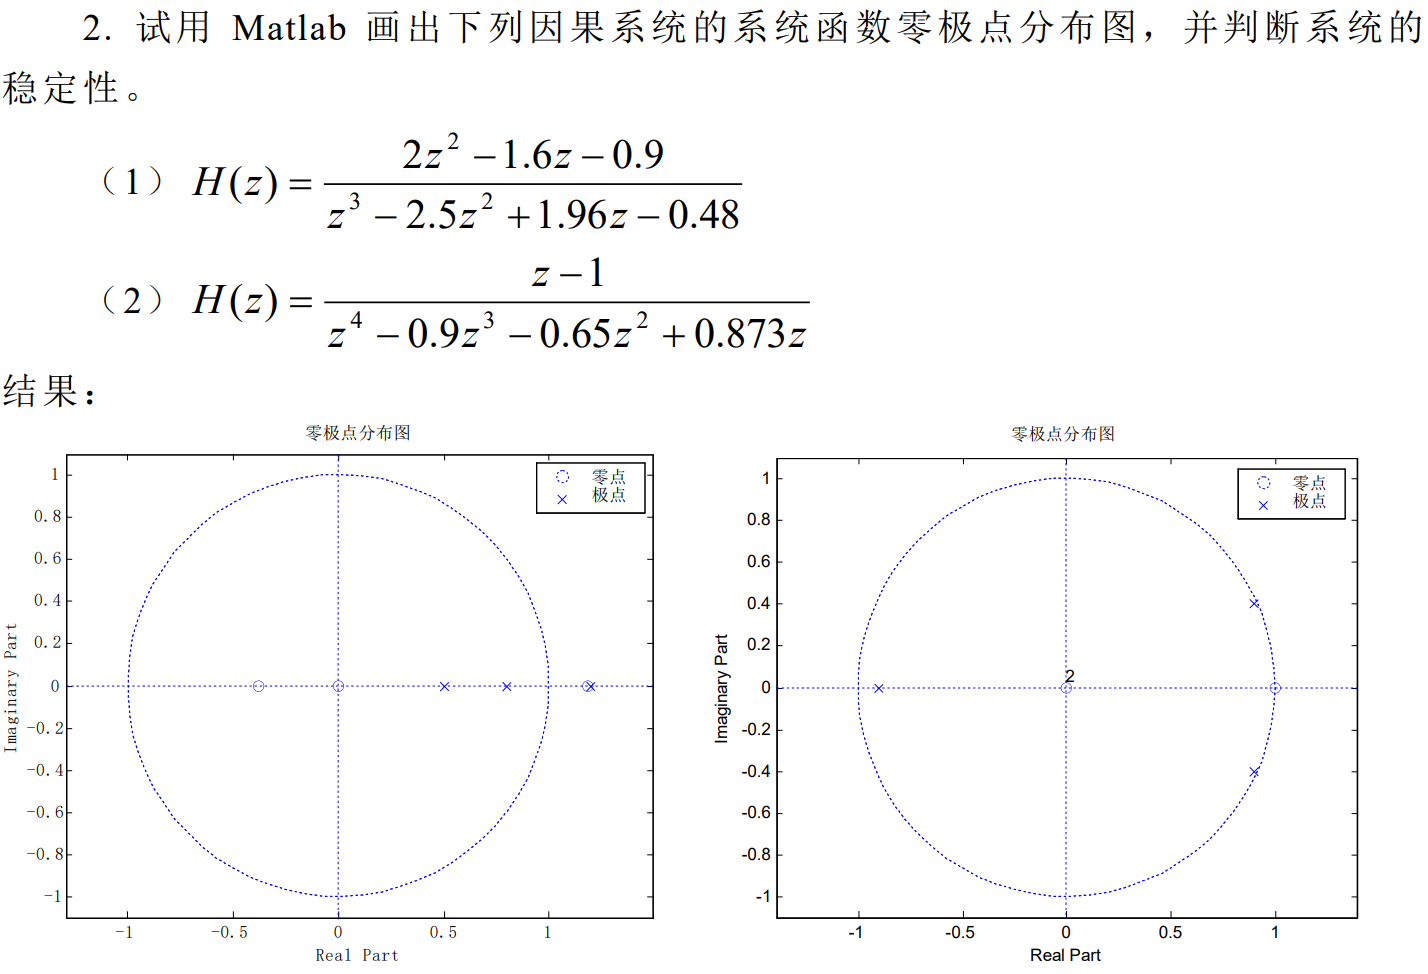

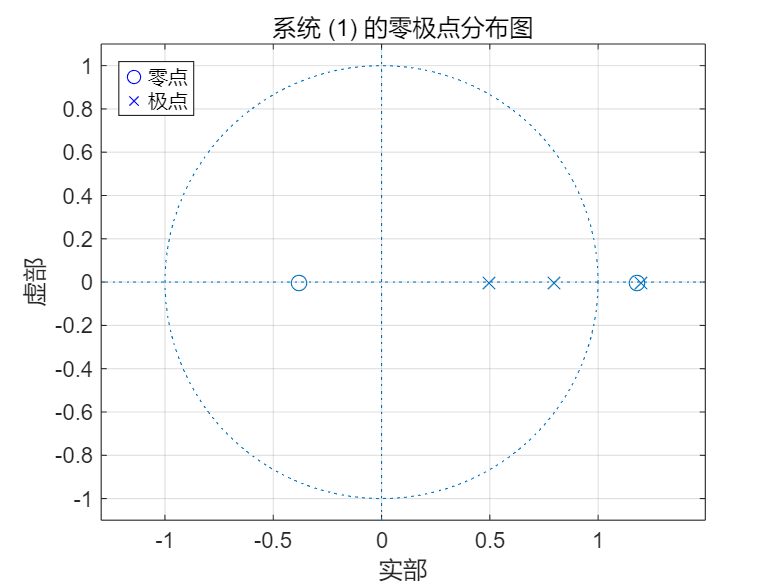

clc;
clear;
close all; 
B1 = [0, 2, -1.6, -0.9];
A1 = [1, -2.5, 1.96, -0.48];

% 1. 绘制零极点图
figure(1); % 创建第一个图形窗口
zplane(B1, A1);

hold on;
h1 = plot(NaN, NaN, 'o', 'MarkerEdgeColor', 'b');
h2 = plot(NaN, NaN, 'x', 'MarkerEdgeColor', 'b');
% 创建一个只包含这两个句柄的图例
legend([h1, h2], {'零点', '极点'}, 'Location', 'northwest');
hold off;

title('系统 (1) 的零极点分布图');
grid on;


% 2. 判断稳定性
% 系统的稳定性由极点的位置决定，极点是分母多项式的根
poles1 = roots(A1);
mags1 = abs(poles1); % 计算所有极点的模长

% 在命令窗口显示结果
disp('--- 系统 (1) ---');

--- 系统 (1) ---


disp('极点位置 (Poles):');

极点位置 (Poles):


disp(poles1);

    1.2000
    0.8000
    0.5000



disp('极点模长 (Magnitudes):');

极点模长 (Magnitudes):


disp(mags1);

    1.2000
    0.8000
    0.5000




% 对于因果系统，所有极点的模长都必须小于 1，系统才稳定
if all(mags1 < 1)
    disp('结论: 系统 (1) 稳定 (所有极点都在单位圆内部)。');
else
    disp('结论: 系统 (1) 不稳定 (存在极点在单位圆上或单位圆外)。');
end

结论: 系统 (1) 不稳定 (存在极点在单位圆上或单位圆外)。


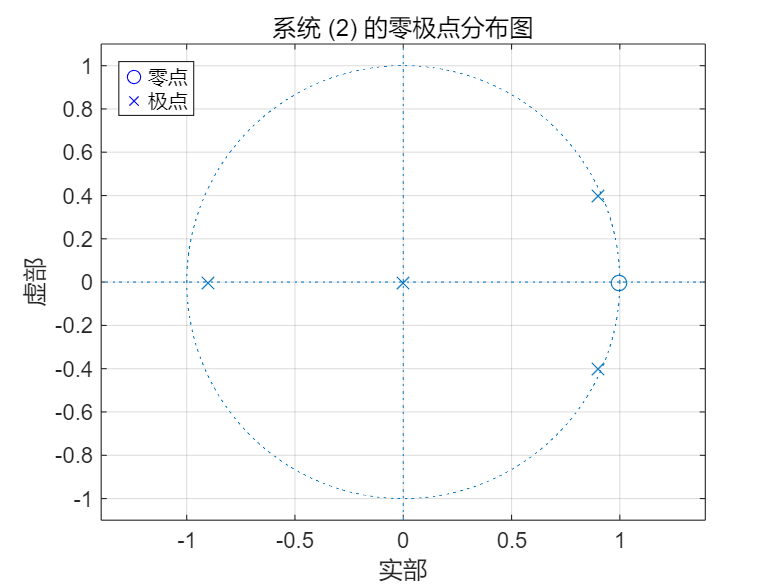




B2 = [0, 0, 0, 1, -1]; 
A2 = [1, -0.9, -0.65, 0.873, 0];

% 1. 绘制零极点图
figure(2); % 创建第二个图形窗口
zplane(B2, A2);
hold on;
h1 = plot(NaN, NaN, 'o', 'MarkerEdgeColor', 'b');
h2 = plot(NaN, NaN, 'x', 'MarkerEdgeColor', 'b');
% 创建一个只包含这两个句柄的图例
legend([h1, h2], {'零点', '极点'}, 'Location', 'northwest');
hold off;
title('系统 (2) 的零极点分布图');
grid on;


% 2. 判断稳定性
poles2 = roots(A2);
mags2 = abs(poles2);

% 在命令窗口显示结果
disp(' '); % 打印一个空行以作分隔

disp('--- 系统 (2) ---');

--- 系统 (2) ---


disp('极点位置 (Poles):');

极点位置 (Poles):


disp(poles2);

   0.0000 + 0.0000i
  -0.9000 + 0.0000i
   0.9000 + 0.4000i
   0.9000 - 0.4000i



disp('极点模长 (Magnitudes):');

极点模长 (Magnitudes):


disp(mags2);

         0
    0.9000
    0.9849
    0.9849




if all(mags2 < 1)
    disp('结论: 系统 (2) 稳定 (所有极点都在单位圆内部)。');
else
    disp('结论: 系统 (2) 不稳定 (存在极点在单位圆上或单位圆外)。');
end

结论: 系统 (2) 稳定 (所有极点都在单位圆内部)。


3.

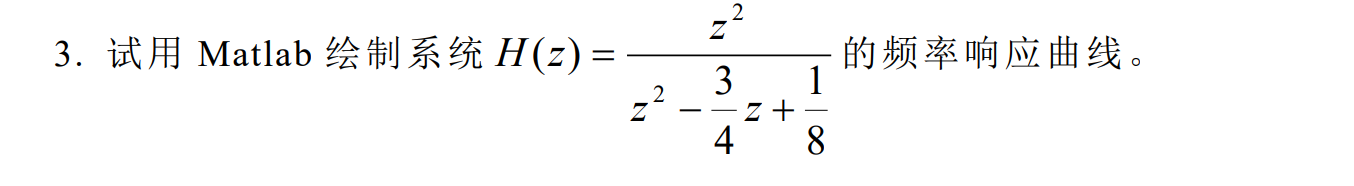

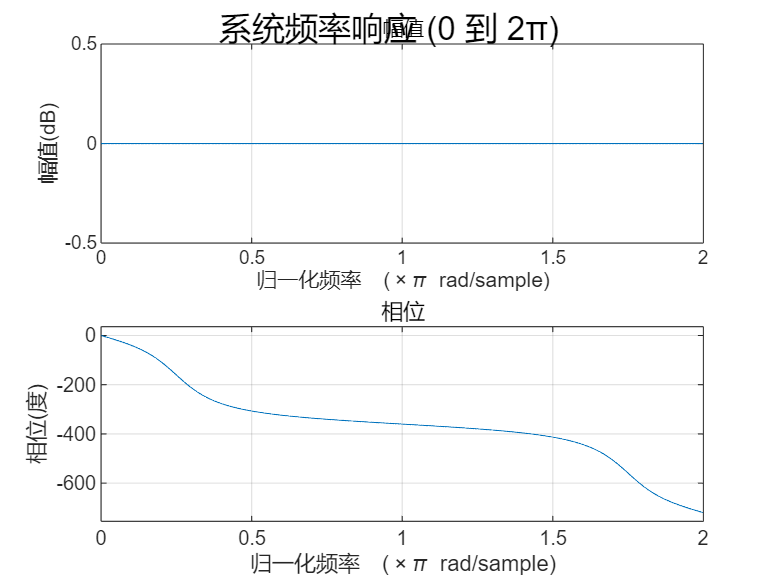

b = [1 0 0];
a = [1 -0.75 0.125];
[H,w] = freqz(b,a,400,'whole');
Hm = abs(H);
Hp = angle(H);
subplot(211)

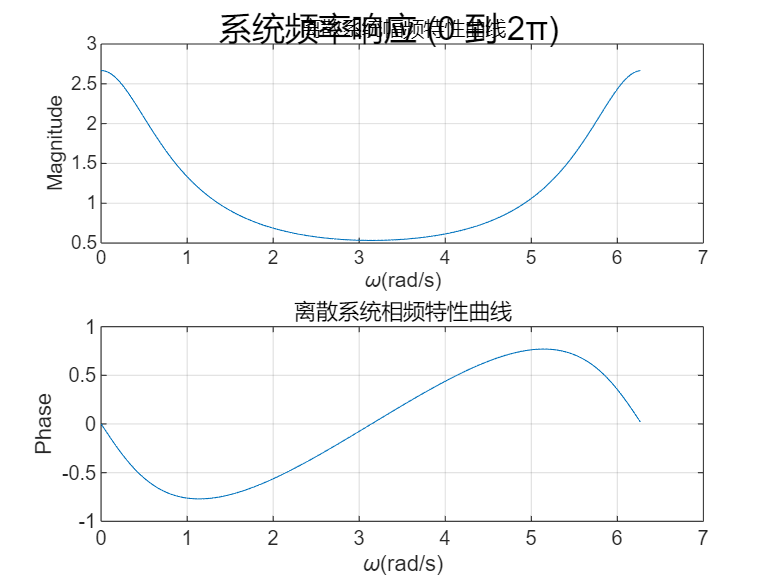

plot(w,Hm),grid on
xlabel('\omega(rad/s)'),ylabel('Magnitude')
title('离散系统幅频特性曲线')
subplot(212)
plot(w,Hp),grid on
xlabel('\omega(rad/s)'),ylabel('Phase')
title('离散系统相频特性曲线')

4.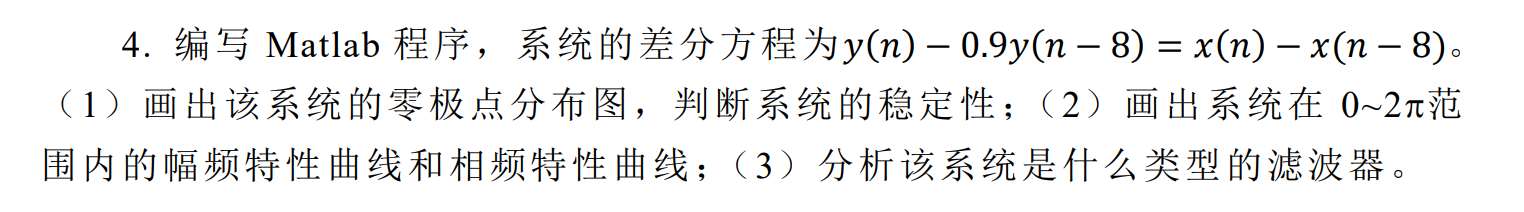

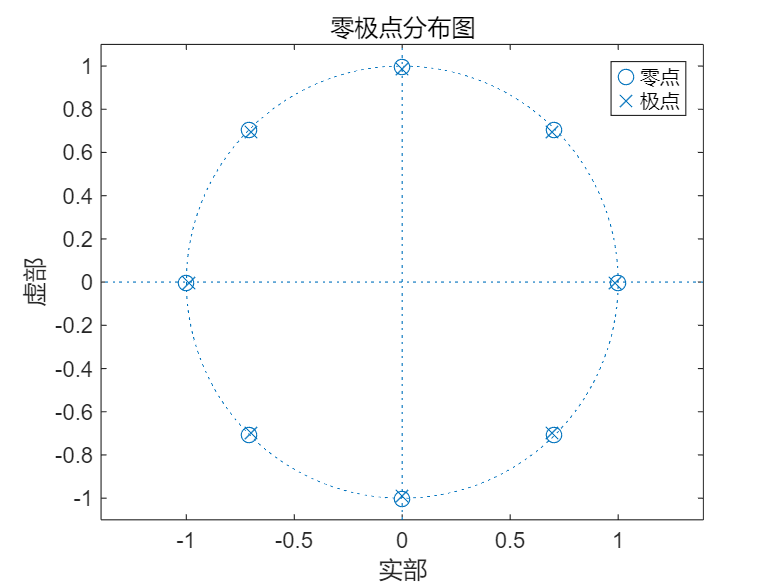

A4=[1,0,0,0,0,0,0,0,-0.9];
B4=[1,0,0,0,0,0,0,0,-1];
figure;
zplane(B4,A4);
legend('零点','极点'),title('零极点分布图');

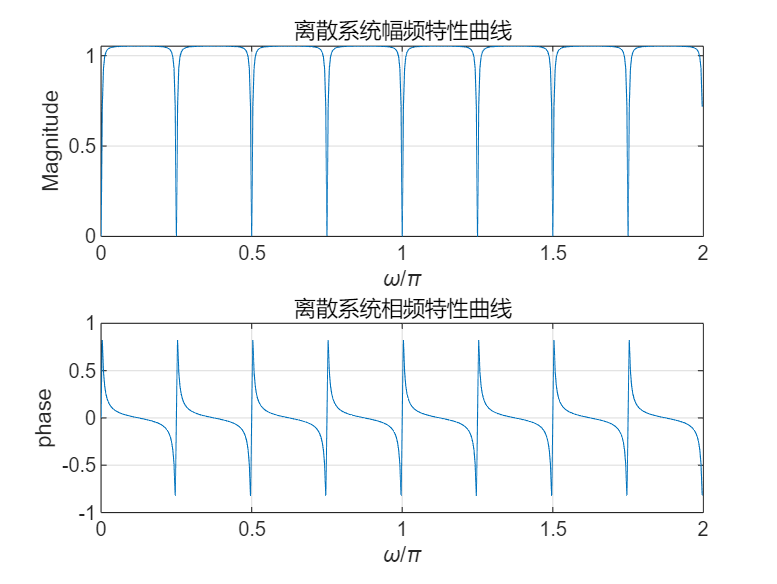

figure;
[H4,w4]=freqz(B4,A4,512,'whole');
Hm4=abs(H4);
Hp4=angle(H4);
subplot(211);
plot(w4./pi,Hm4),grid on;
xlabel('\omega/\pi'),ylabel('Magnitude');
title('离散系统幅频特性曲线');
subplot(212);
plot(w4./pi,Hp4),grid on;
xlabel('\omega/\pi'),ylabel('phase');
title('离散系统相频特性曲线');

思考题

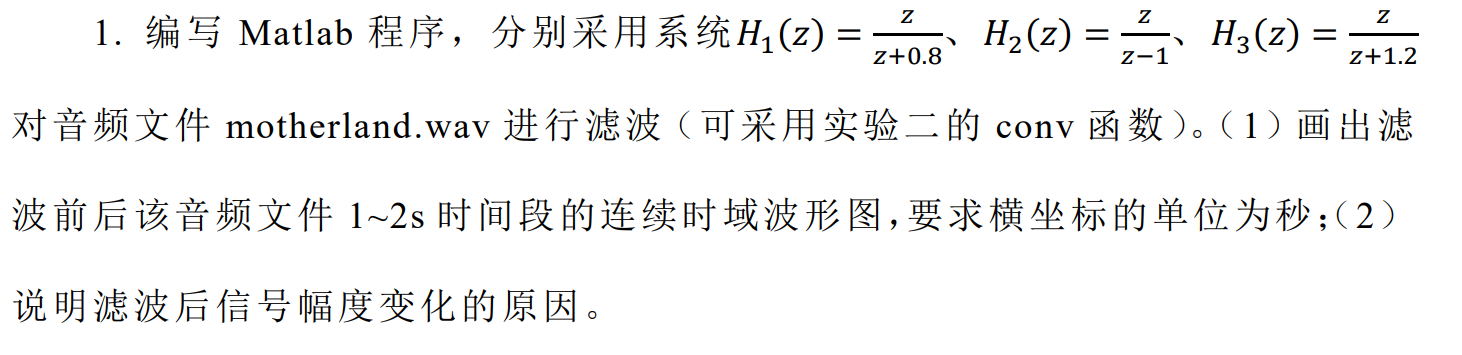

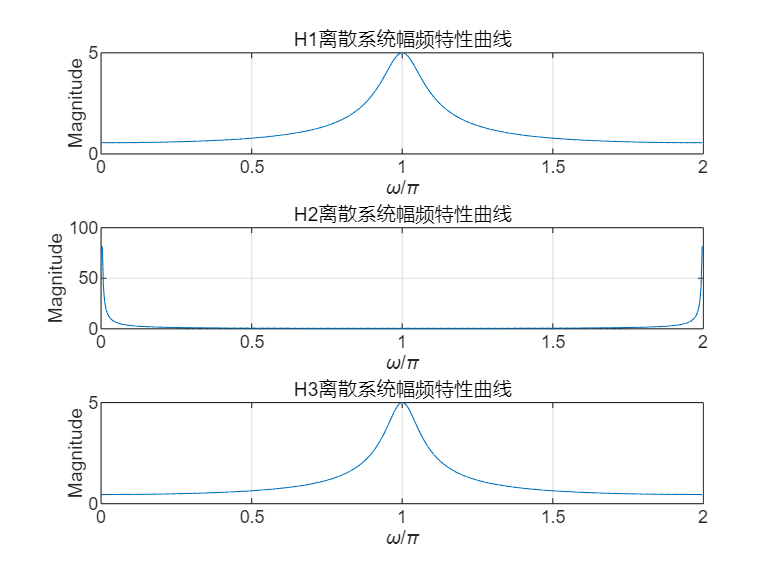

% 滤波器设计
B1 = [1, 0];
A1 = [1, 0.8];
B2 = [1, 0];
A2 = [1, -1];
B3 = [1, 0];
A3 = [1, 1.2];
% 绘制特性曲线
figure('Name', '特性曲线');
[H1, w1] = freqz(B1, A1, 'whole');
Hm1 = abs(H1);
subplot(311);
plot(w1./pi, Hm1);
grid on;
xlabel('\omega/\pi'),ylabel('Magnitude');
title('H1离散系统幅频特性曲线');
[H2, w2] = freqz(B2, A2, 'whole');
Hm2 = abs(H2);
subplot(312);
plot(w2./pi, Hm2);
grid on;
xlabel('\omega/\pi'),ylabel('Magnitude');
title('H2离散系统幅频特性曲线');
[H3, w3] = freqz(B3, A3, 'whole');
Hm3 = abs(H3);
subplot(313);
plot(w3./pi, Hm3);
grid on;
xlabel('\omega/\pi'),ylabel('Magnitude');
title('H3离散系统幅频特性曲线');

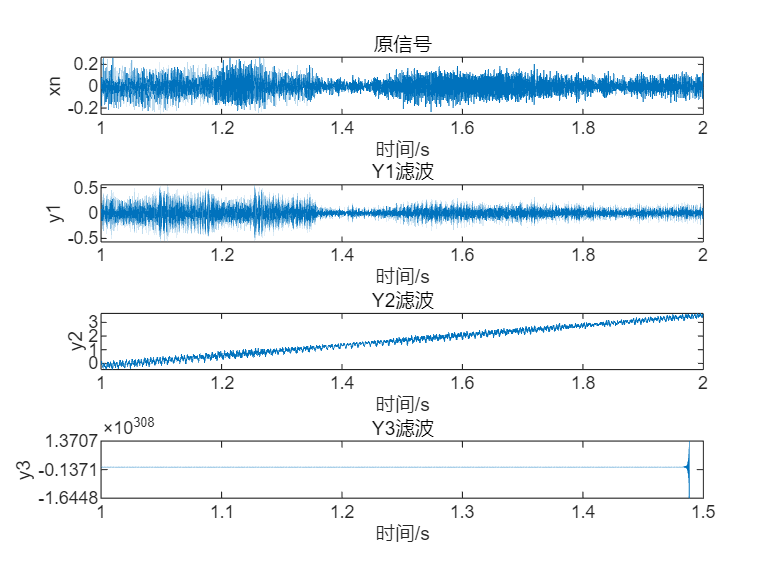


% 读取音频文件
[xn, fs] = audioread('motherland.wav');
% 信号滤波
t = 8000:16000;
y1 = filter(B1, A1, xn(8000:16000));
y2 = filter(B2, A2, xn(8000:16000));
y3 = filter(B3, A3, xn(8000:16000));
% 播放滤波后的信号
sound(y1, fs);
% 绘制滤波信号
figure('Name', '滤波信号');
subplot(4, 1, 1);
plot(t/8000, xn(t));
xlabel('时间/s'),ylabel('xn'),title('原信号');
subplot(4, 1, 2);
plot(t/8000, y1);
xlabel('时间/s'),ylabel('y1'),title('Y1滤波');
subplot(4, 1, 3);
plot(t/8000, y2);
xlabel('时间/s'),ylabel('y2'),title('Y2滤波');
subplot(4, 1, 4);
plot(t/8000, y3);
xlabel('时间/s'),ylabel('y3'),title('Y3滤波');

2.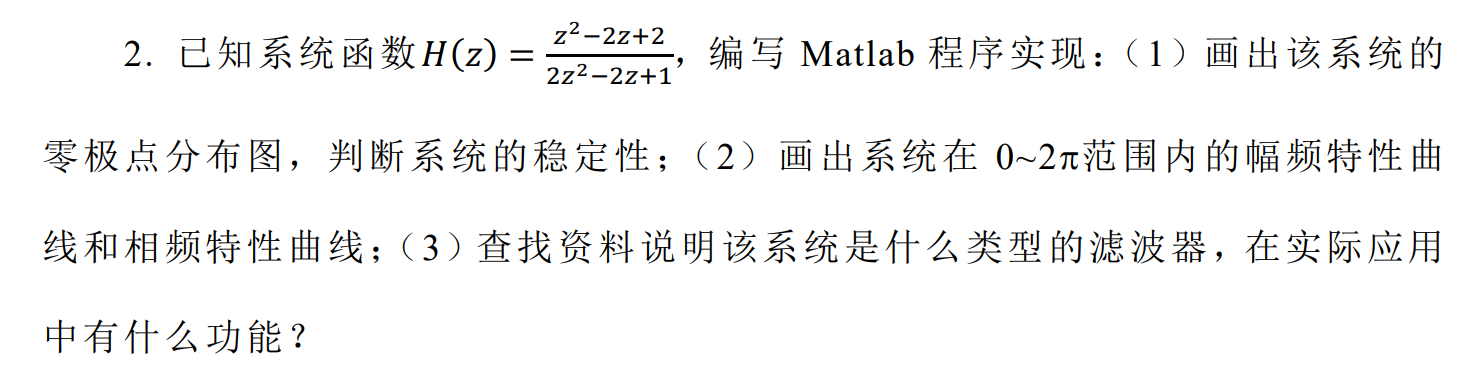

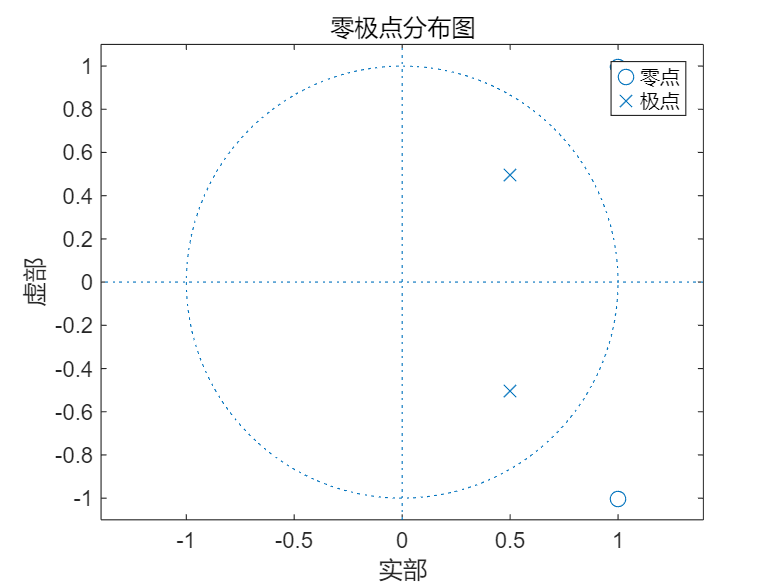

B = [1, -2, 2];
A = [2, -2, 1];
% 绘制极点-零点图
figure;
zplane(B, A);
legend('零点','极点'),title('零极点分布图');

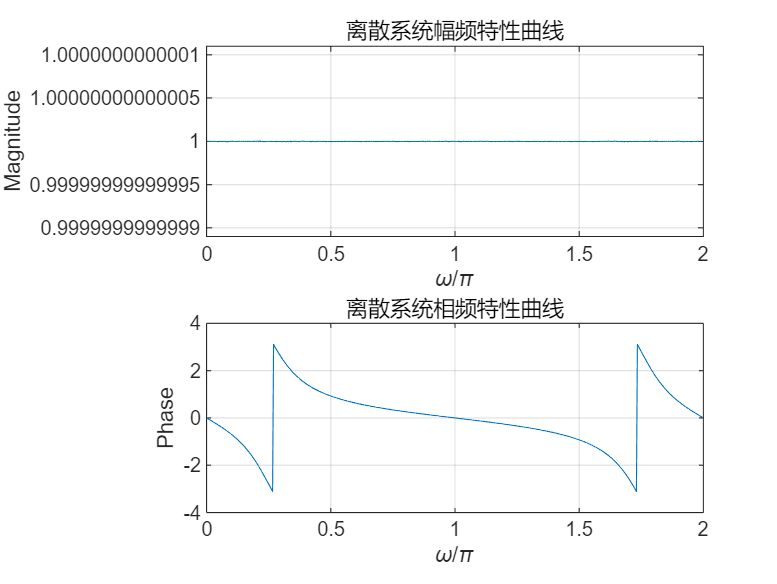

% 计算幅频和相频特性
[H, w] = freqz(B, A, 512,'whole');
Hm = abs(H);
Hp = angle(H);
figure;
subplot(211);
plot(w./pi, Hm),grid on;
xlabel('\omega/\pi'),ylabel('Magnitude');
title('离散系统幅频特性曲线');
subplot(212);
plot(w./pi, Hp),grid on;
xlabel('\omega/\pi'),ylabel('Phase');
title('离散系统相频特性曲线');